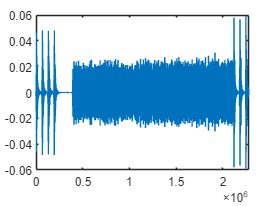

K = 2048;
L = 200;
Fc = 24000;
B = 8000;
W = 24;
Lambda = 24;
Sampler = 256000;
vel = 1.03;
c = 1500;
%a = vel/c;
%%% Step 0 Load the .mat files
load("test_rece_data_173048_1472.mat");
load("pilot_signal_for_synchronization.mat");
load("ofdm_map.mat");
load("benchmark_parameter_174623_1472.mat");
load("benchmark_rece_data_174623_1472.mat");
load("benchmark_Zw_174623_1472.mat");
load("itc_1007_compfilter.mat");
%%% Step 1: PB filter to remove noise beyond PB
y_in = rece_data_ofdm_bench; %load benchmark_rece_data_174623_1472.mat
%ypb = zeros(length(y_in), 1);
y_pb = bandpass(y_in, [-1000+Fc, 8000+Fc], Sampler);
plot(y_pb);


%%% Step 2: Estimate a
T_tx = 8269.52; %In ms
T_txs = T_tx / 1000; %In sec
sr = 1 / Sampler; %Sampling rate in seconds
T_rx_est = 2117460 * sr; %Estimated Trx duration in sec
% a = T_txs/T_rx_est-1 % The minus 1 was missing before
a_est = a_est_174623 %TA's given a_hat value, load benchmark_parameter_174623_1472.mat

a_est = 5.0000e-05

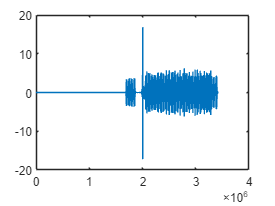

%%% Step 3: Resampling
%y_pb_re = resample(y_pb, round((1+a)*1*exp(5)), round(1*exp(5))); %%% Double check with TA
y_pb_re = resample(y_pb, round((1+a_est)*1*exp(5)), round(1*exp(5)));
%%% Step 4: Resampling from 256k to 192k
Ls = 192;
Ms = 256;
Lp = 24;
N = Lp*Ls-1;
h = Ls*fir1(N, 1/Ms, kaiser(N+1, 7.8562));
Ytilda_pb_re = upfirdn(y_pb_re, h, Ls, Ms);
%plot(Ytilda_pb_re);
%freqz(Ytilda_pb_re, 1);

%%% Step 5: Synchronization
pilot = OFDM_data_pre_old; %load pilot_signal_for_syncronizaation.mat
%plot(pilot);

correlate = xcorr(Ytilda_pb_re, pilot); % Correlation with pilot signal
plot(correlate);

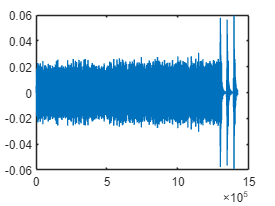


i = max(correlate); % Finds max value index for n_0
for j = 1:length(correlate)
    if i == correlate(j)
        n_0 = j - length(Ytilda_pb_re);
    end
end

Ytilda_n0 = Ytilda_pb_re(n_0:end);    % Truncates signal to start at n_0
plot(Ytilda_n0)

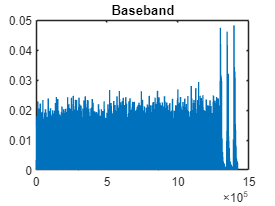


%%% Step 6 Convolution for PB -> BB
Ytilda_conv = conv(Ytilda_n0, h_comp); % Convolution with 101 sample vector
%plot(Ytilda_conv)
Ytilda_no_delay = Ytilda_conv(51:end); % Cut out first 50 data points of delay

%%% Step 7 PB -> BB
Y_BB_I = zeros(1, length(Ytilda_no_delay)); % Preallocate arrays for processing speed
Y_BB_Q = zeros(1, length(Ytilda_no_delay));
Y_BB = zeros(1, length(Ytilda_no_delay));
for n = 1:length(Ytilda_no_delay)   % As seen in handout
Y_BB_I(n) = Ytilda_no_delay(n)*2*cos(2*pi*Fc*n*1/Sampler);
Y_BB_Q(n) = -Ytilda_no_delay(n)*2*sin(2*pi*Fc*n*1/Sampler);
Y_BB(n) = Y_BB_I(n) + 1i*Y_BB_Q(n);
end

%plot(Y_BB)

%%% Step 8 Raised Cosine Convolution
beta = .125; % roll-off factor
Fs = 192000; % sampling frequency
Fd = 8000; % data/transfer rate
lamda_oversamp = Fs/Fd; % lambda = 24 defined above works too
delay = 100;    % Given delay in part 1 before oversampling
span = 2*delay;
Rn = rcosdesign(beta, span, Fs/Fd, 'sqrt'); % rcosine filter (similar to sinc function)
%plot(Rn)
plot(abs(Y_BB));    % Checking signal before filtering
title("Baseband");

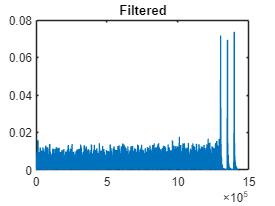

Y_BB_filtered = conv(Y_BB, Rn); % Same as part 1 Step 5
plot(abs(Y_BB_filtered))    % Checking signal after filtering
title("Filtered");

%plot(real(fft(Y_BB)))
delay_os = length(Y_BB_filtered)-length(Y_BB)   % Delay obtained by difference of signal lengths 

delay_os = 4800

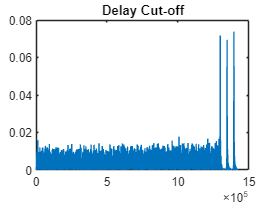

Y_BB_no_delay = Y_BB_filtered(delay_os/2+1:length(Y_BB_filtered)-delay_os/2);   % Cuts out delay
plot(abs(Y_BB_no_delay));   % Should be the same length as Y_BB
title("Delay Cut-off");

%%% Step 9
% Ts = 1/Fs;
% for n_0_1 = 2200:1:2400
%     for epsilon_1 = -2:0.1:2
%         Y_BB_1(n) = 
%     end
% end